# Deep Learning

## Load and split data

The example images are stored in the folder `Spectrograms`. The data for each instrument is seperated in subfolders, labelled by the folder name.

Split the data so that 80% of the images are used for trainingand 20% are used for testing.

img_ds = imageDatastore("Classify Spectrograms (test)/Projects" + ...
    "/MusicProject/Spectrograms","IncludeSubfolders",true, ...
    "LabelSource","foldernames");
[trainImgs,testImgs] = splitEachLabel(img_ds,0.8,"randomized");

#### Resize the data datastores so that the images are `[224 224]`.

trainReImg = augmentedImageDatastore([224 224],trainImgs)

trainReImg =   augmentedImageDatastore with properties:

             NumObservations: 1338
                       Files: {1338×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testReImg = augmentedImageDatastore([224 224],testImgs)

testReImg =   augmentedImageDatastore with properties:

             NumObservations: 335
                       Files: {335×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


Visualize the first image in datastore and the first image from train images have resized.

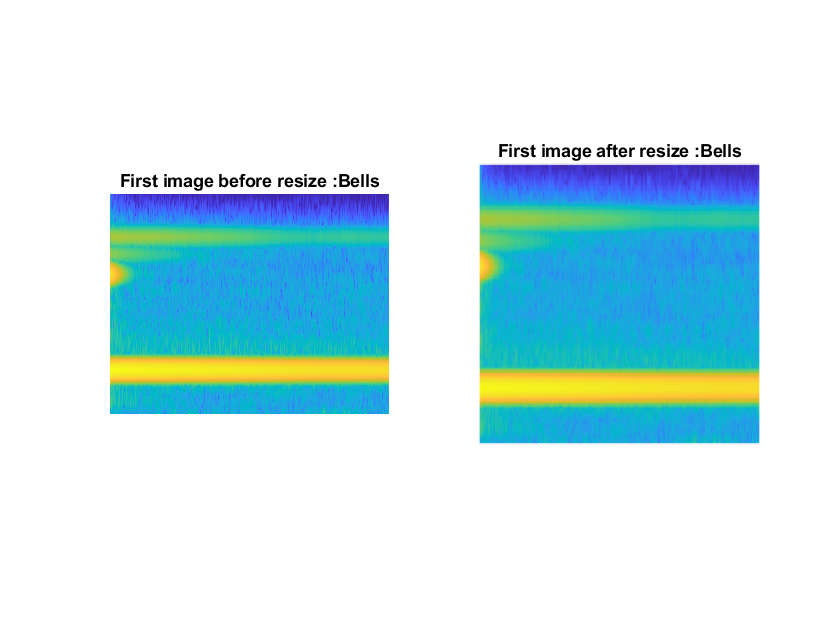

img_1 = readimage(img_ds,1);
label = img_ds.Labels(1);

figure(1)
subplot(1,2,1,"replace")
imshow(img_1)
title("First image before resize :" + string(label))


subplot(1,2,2,"replace")
data = readByIndex(trainReImg,1);
img = cell2mat(data.input);
imshow(cell2mat(data.input))
title("First image after resize :" + string(label))

## Pretrained Network

pretrained network : resnet50

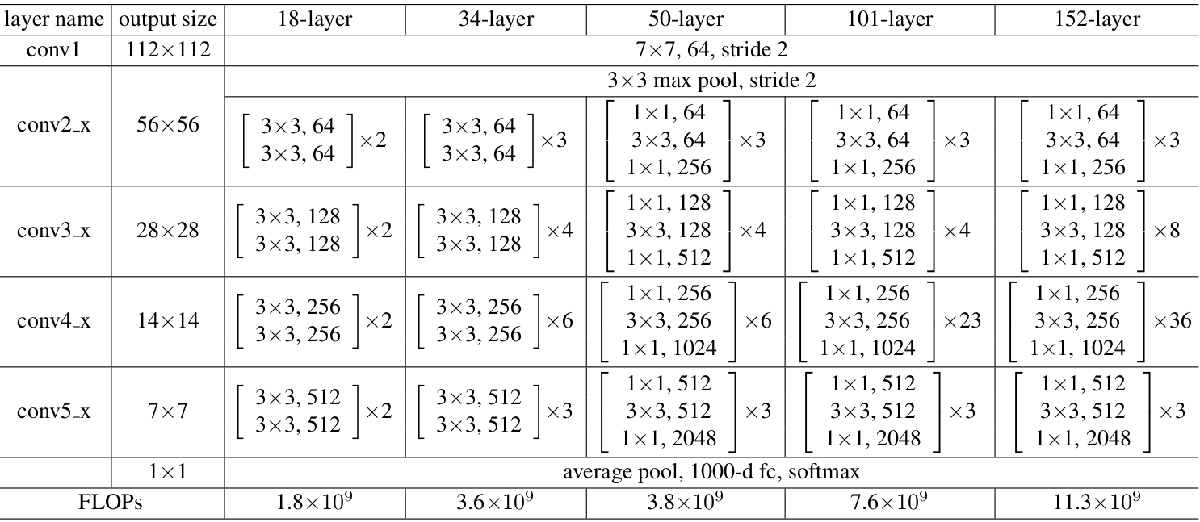

net = resnet50;
all_layer = net.Layers

all_layer =   177×1 Layer array with layers:

     1   'input_1'                      Image Input              224×224×3 images with 'zerocenter' normalization
     2   'conv1'                        Convolution              64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'bn_conv1'                     Batch Normalization      Batch normalization with 64 channels
     4   'activation_1_relu'            ReLU                     ReLU
     5   'max_pooling2d_1'              Max Pooling              3×3 max pooling with stride [2  2] and padding [1  1  1  1]
     6   'res2a_branch2a'               Convolution              64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'bn2a_branch2a'                Batch Normalization      Batch normalization with 64 channels
     8   'activation_2_relu'            ReLU                     ReLU
     9   'res2a_branch2b'      

## Visualize Convolutional Neural Network

Visualize output when image passing each layers

#### Convolution Layer

output size = (inputSize - DilationFactor*(FilterSize-1) + 2*paddingSize) / strideSize + 1

firstConvName = net.Layers(2).Name;
imgConv = activations(net,img,firstConvName);

%Visualize properties in the first convolution layers
firstConv = net.Layers(2)

firstConv =   Convolution2DLayer with properties:

              Name: 'conv1'

   Hyperparameters
        FilterSize: [7 7]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [3 3 3 3]

   Learnable Parameters
           Weights: [7×7×3×64 single]
              Bias: [1×1×64 single]

  Show all properties


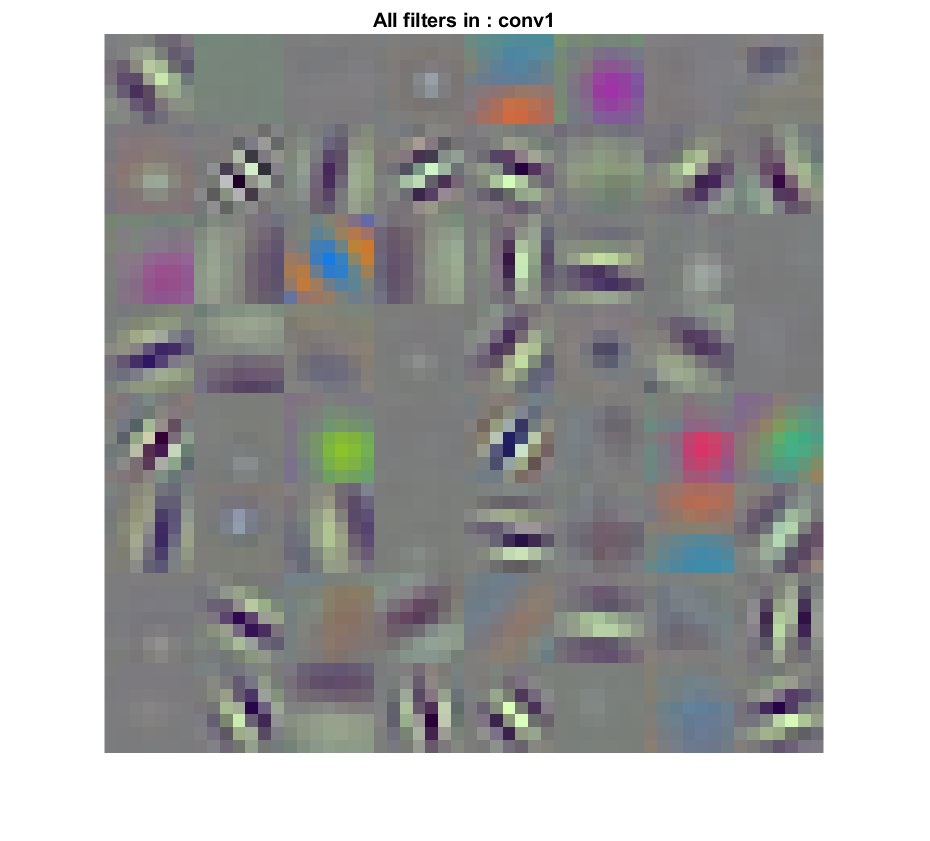


%Display all the filters in "conv1" (convert to gray scale before display all the filters)
figure()
montage(mat2gray(net.Layers(2).Weights))
title("All filters in : " + string(firstConvName))

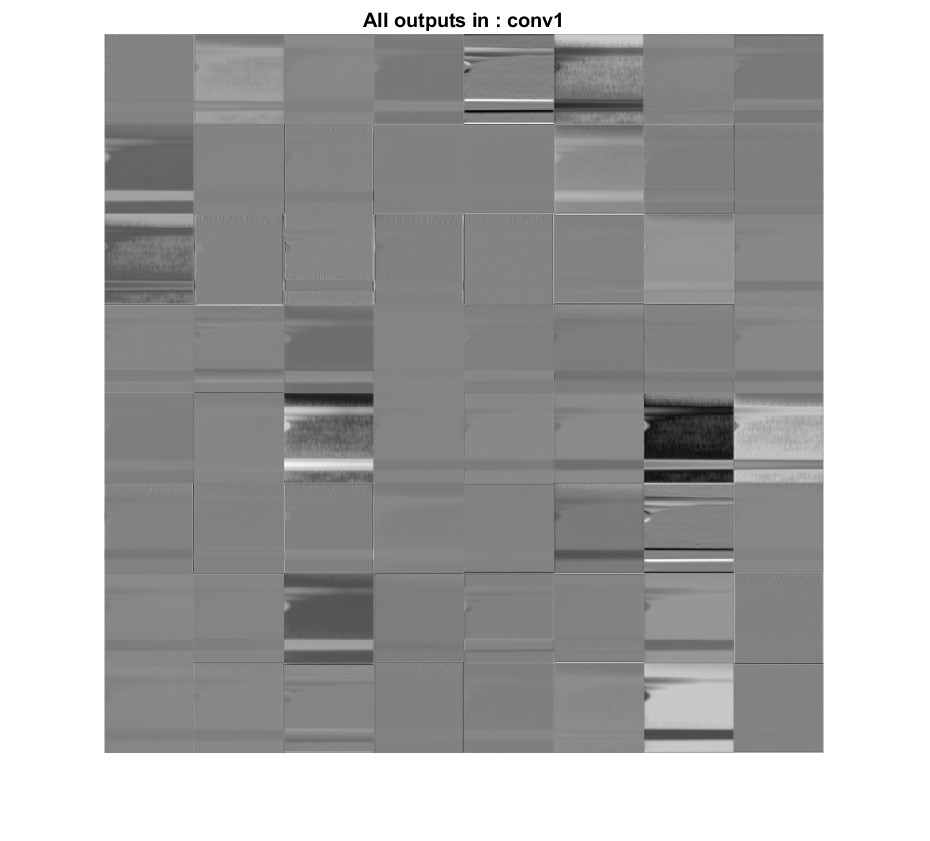


%Display all outputs
figure()
montage(mat2gray(imgConv))
title("All outputs in : " + string(firstConvName))

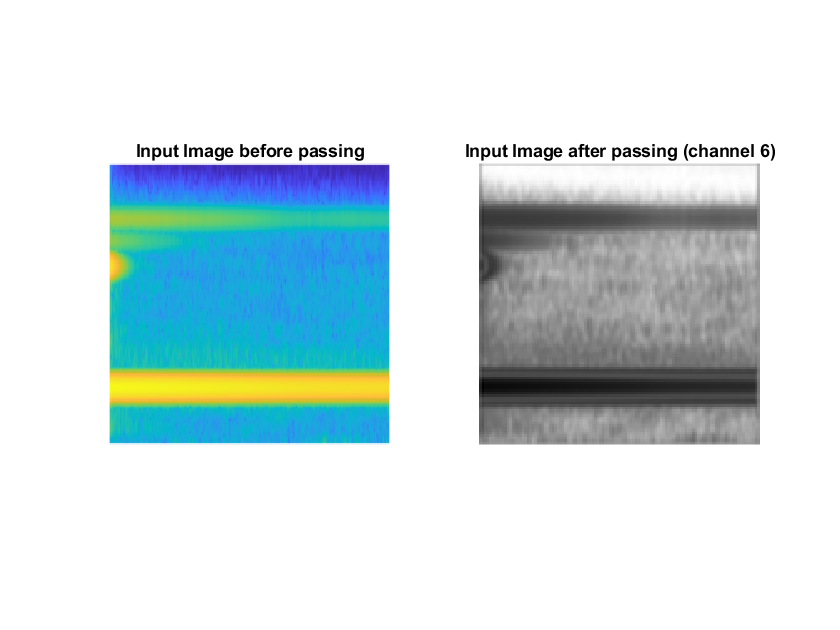


%Display the first image before and after passing this layer.
figure(4)
subplot(1,2,1)
imshow(img)
title("Input Image before passing")
subplot(1,2,2)
imshow(mat2gray(imgConv(:,:,6)))
title("Input Image after passing (channel 6)")

#### Batch Normalization Layer

example calculated

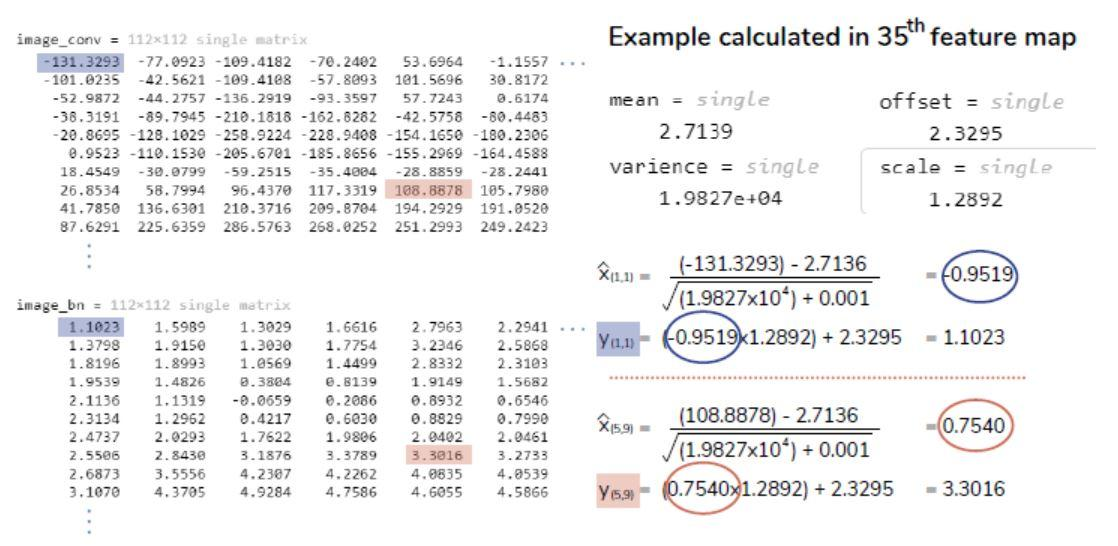

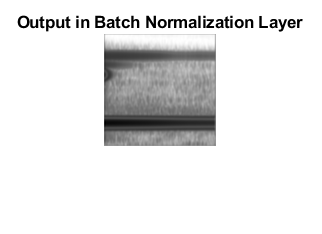

batchNormName = net.Layers(3).Name;
imgBatch = activations(net,img,batchNormName);

%display output
figure(5)
imshow(imgBatch(:,:,6),[])
title("Output in Batch Normalization Layer")

#### ReLU Layer

ReLU function :

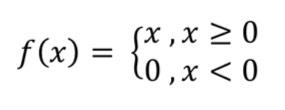

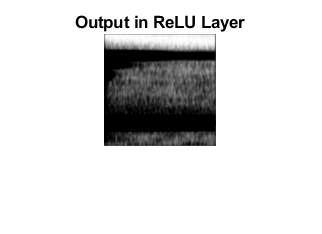

reluName = net.Layers(4).Name;
imgReLU = activations(net,img,reluName);
imshow(imgReLU(:,:,6),[])
title("Output in ReLU Layer")

**Visualize only 6th feature map.**

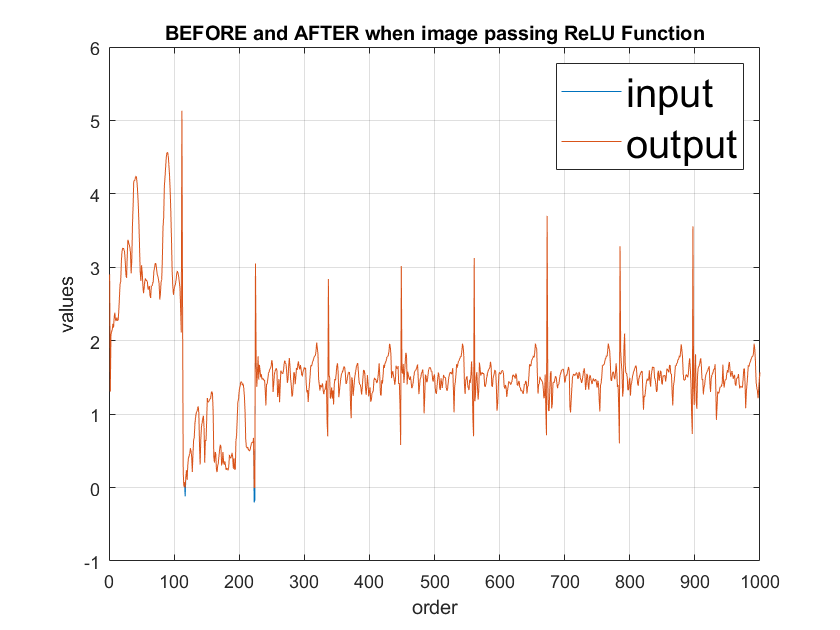

%example in channel 6 (6th feature map)
n = 1:1000;
imgBN_col = activations(net,img,batchNormName,"outputAs","column");
imgReLU_col = activations(net,img,reluName,"outputAs","column");

figure()
plot(n,imgBN_col(n,1),n,imgReLU_col(n,1))
grid()
legend("input","output","fontsize",20)
xlabel("order")
ylabel("values")
title("BEFORE and AFTER when image passing ReLU Function")

BNvalues = imgBatch(:,:,6)

BNvalues = 112×112 single matrix
    4.2836    5.9378    6.4155    6.4482    6.4901    6.4035    6.4240    6.4683    6.5120    6.4068    6.3369    6.4170    6.4653    6.4544    6.4089    6.3699    6.3967    6.4455    6.3743    6.2796    6.3172    6.3763    6.3909    6.4033    6.3567    6.2694    6.2498    6.3900    6.3492    6.2265    6.2038    6.2002    6.1908    6.1625    6.1550    6.2282    6.2773    6.3021    6.3476    6.4219    6.3270    6.1725    6.2375    6.3055    6.3218    6.3112    6.2034    6.1434    6.1695    6.1664
    5.1143    7.5825    8.2907    8.3160    8.4271    8.3872    8.4360    8.5055    8.5692    8.3997    8.3348    8.4556    8.4984    8.4989    8.4497    8.3654    8.4180    8.4888    8.3777    8.2737    8.3407    8.4046    8.4371    8.4422    8.3407    8.2553    8.2507    8.4036    8.2908    8.1602    8.1709    8.2287    8.2197    8.1668    8.1382    8.2196    8.2719    8.2899    8.3518    8.4531    8.3200    8.1026    8.1673    8.2329    8.2796    8.2923    8.

RELUvalues = imgReLU(:,:,6)

RELUvalues = 112×112 single matrix
    4.2836    5.9378    6.4155    6.4482    6.4901    6.4035    6.4240    6.4683    6.5120    6.4068    6.3369    6.4170    6.4653    6.4544    6.4089    6.3699    6.3967    6.4455    6.3743    6.2796    6.3172    6.3763    6.3909    6.4033    6.3567    6.2694    6.2498    6.3900    6.3492    6.2265    6.2038    6.2002    6.1908    6.1625    6.1550    6.2282    6.2773    6.3021    6.3476    6.4219    6.3270    6.1725    6.2375    6.3055    6.3218    6.3112    6.2034    6.1434    6.1695    6.1664
    5.1143    7.5825    8.2907    8.3160    8.4271    8.3872    8.4360    8.5055    8.5692    8.3997    8.3348    8.4556    8.4984    8.4989    8.4497    8.3654    8.4180    8.4888    8.3777    8.2737    8.3407    8.4046    8.4371    8.4422    8.3407    8.2553    8.2507    8.4036    8.2908    8.1602    8.1709    8.2287    8.2197    8.1668    8.1382    8.2196    8.2719    8.2899    8.3518    8.4531    8.3200    8.1026    8.1673    8.2329    8.2796    8.2923    

#### Max pooling Layer

output size = (inputSize - poolSize + 2*paddingSize) / strideSize + 1

*example calculated*

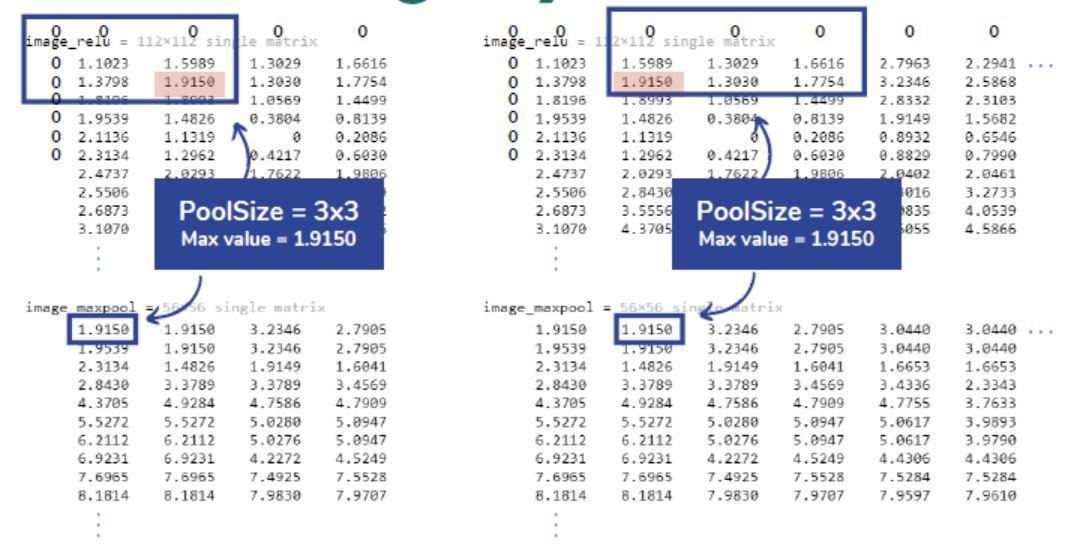

%Max pooling
properties = net.Layers(5)

properties =   MaxPooling2DLayer with properties:

                   Name: 'max_pooling2d_1'
    HasUnpoolingOutputs: 0
             NumOutputs: 1
            OutputNames: {'out'}

   Hyperparameters
               PoolSize: [3 3]
                 Stride: [2 2]
            PaddingMode: 'manual'
            PaddingSize: [1 1 1 1]


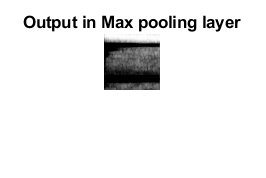

maxPoolName = net.Layers(5).Name;
imgMp = activations(net,img,maxPoolName);

%Display output
imshow(imgMp(:,:,6),[])
title("Output in Max pooling layer")

### Modify final layers for transfer learning

Replace the fully connected layer and classification layer from Resnet50. There are 14 classifications in this dataset.

lgraph = layerGraph(net);
newfc = fullyConnectedLayer(14,"Name","new_fc");
newout = classificationLayer("Name","new_out");

lgraph = replaceLayer(lgraph,"fc1000",newfc);
lgraph = replaceLayer(lgraph,"ClassificationLayer_fc1000",newout);

%Display last layer
all_layer = lgraph.Layers

### Global Average Pooling layer

*example calculated*

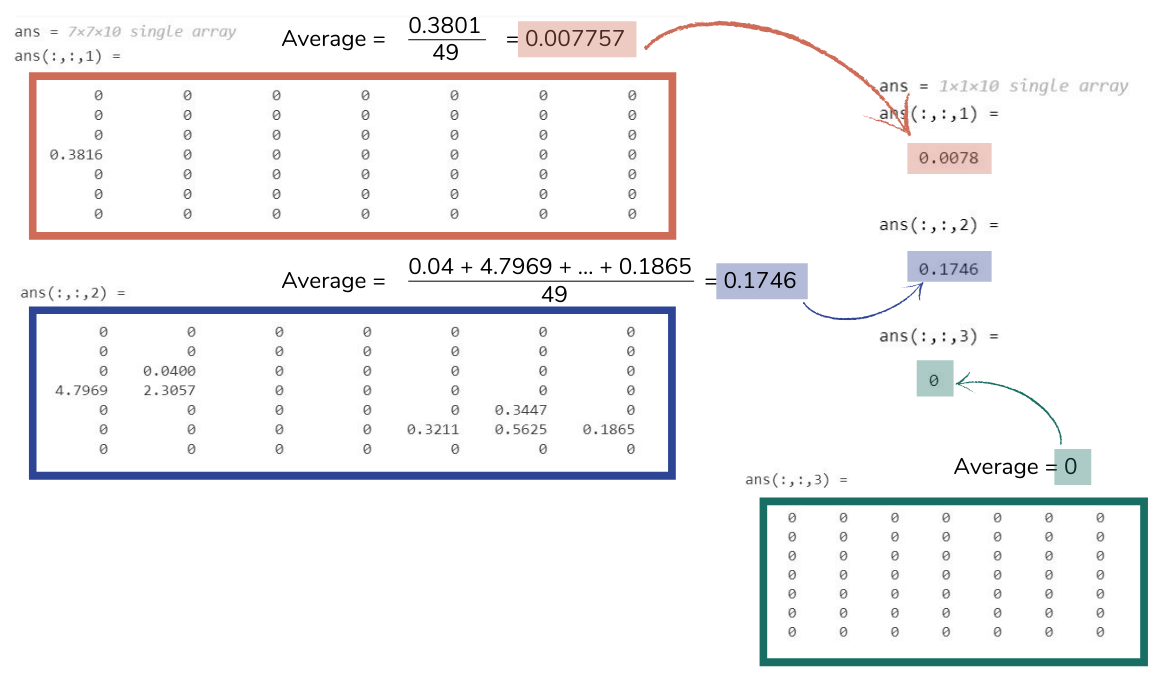

imgLastRelu = activations(net,trainReImg,"activation_49_relu","MiniBatchSize",128);
imgGAP = activations(net,trainReImg,"avg_pool","MiniBatchSize",128);

imgLastRelu(:,:,1:10)
imgGAP(1,1,1:10)

### Fully connected layer

imgFully = activations(net,trainReImg,"fc1000","MiniBatchSize",128,"OutputAs","rows");
imgFully(1:10,1)

### Softmax layer

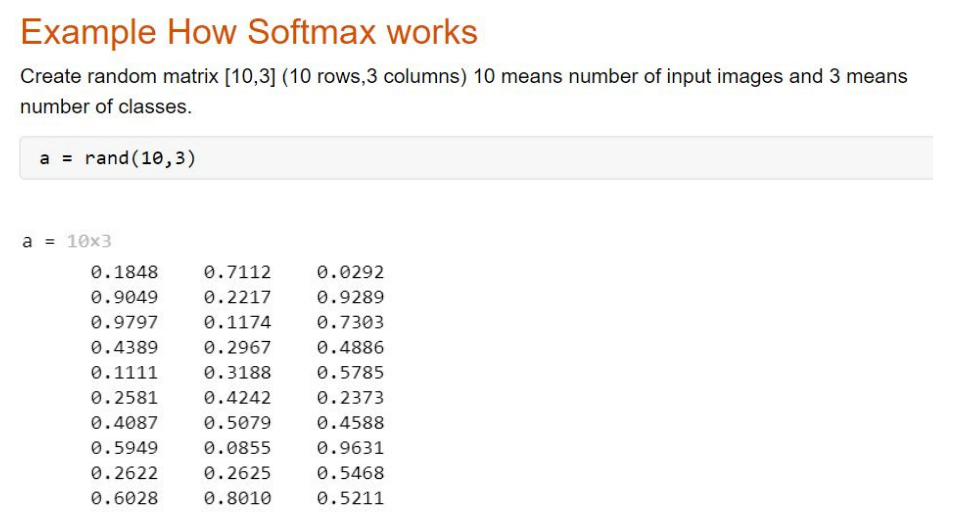

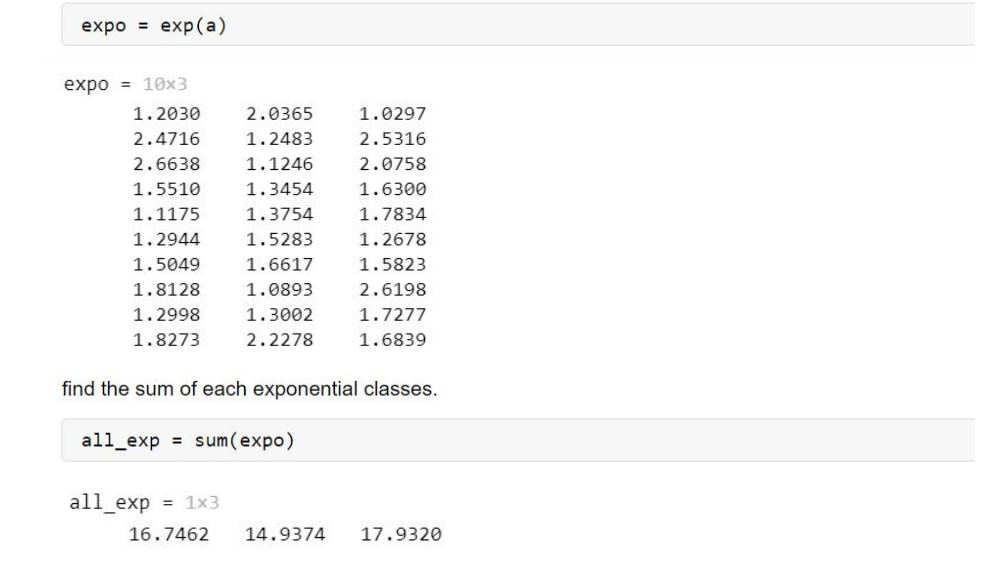

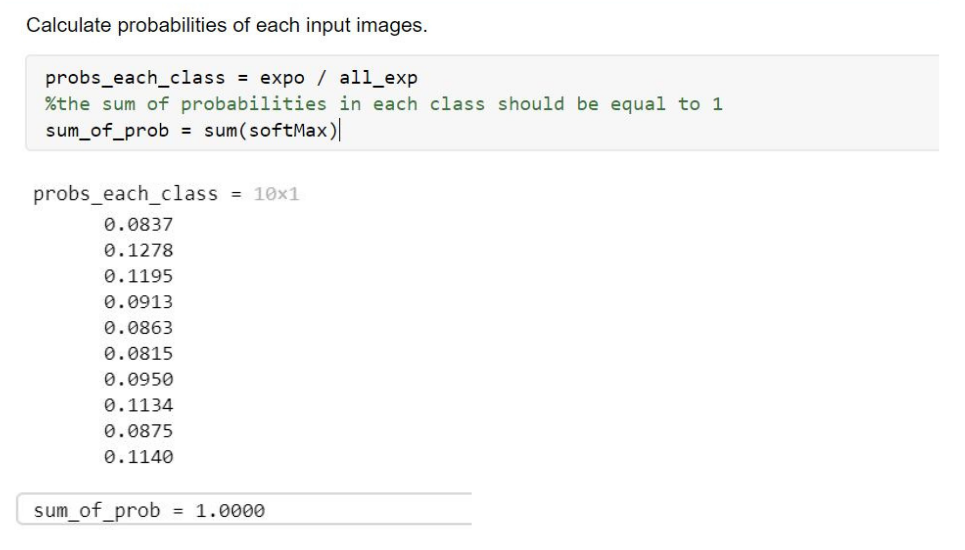

softMax = activations(net,trainReImg,"fc1000_softmax","MiniBatchSize",128,"OutputAs","rows")

output = activations(net,imgrz,"ClassificationLayer_fc1000");
max(output)